# Offline Tensor Analysis (OTA) and Dynamic Tensor Analysis (DTA) for monitoring system

Main challenges

- How to find patterns (main trends) incrementally?

- How to efficiently update the old patterns new data arrive?

- How to utilize the patterns to solve other problems such as anomaly detection and clustering?

In a networking monitoring example

- How to identify anomalies which can signify potential damage to the data?

- Systematic evaluation on large, real datasets, where the tools found patterns and anomalies, and provided large speed-ups over competitors

Laboratorio de Processamento de Sinais em Sistemas Espaciais (LaP2SE):

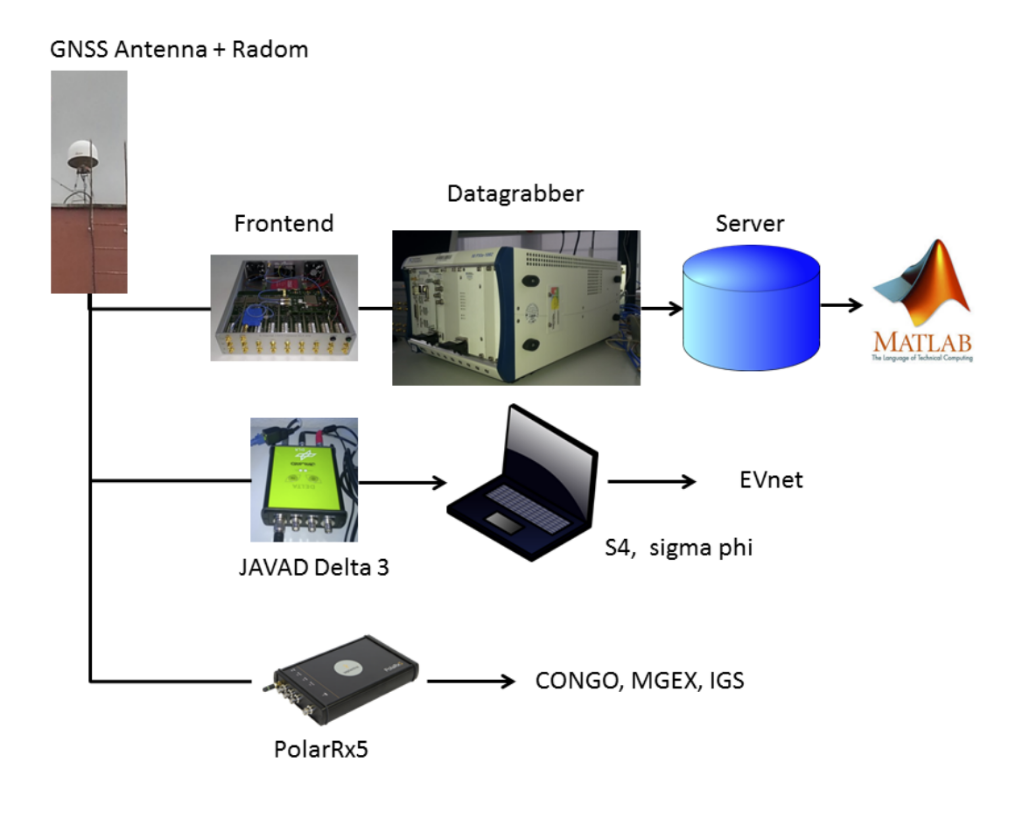

#### Definitions **[1]**:

Tensor sequence: A sequence of Mth order tensor ${\underline{\mathbf{X}} }_{\;1}$, ${\underline{\mathbf{X}} }_{\;2}$, ..., ${\underline{\mathbf{X}} }_{\;n}$ where each ${\underline{\mathbf{X}} }_{\;i} \in R^{I_1 \times I_2 \times \cdots \times I_N }$, for $i\le n$, being $n$ a **fixed** natural number. That is, ${\left\lbrace {\underline{\mathbf{X}} }_{\;i} \right\rbrace }_{i=1}^n$

Tensor stream**: **A sequence of Mth order tensor ${\underline{\mathbf{X}} }_{\;1}$, ${\underline{\mathbf{X}} }_{\;2}$, ..., ${\underline{\mathbf{X}} }_{\;n}$ where each ${\underline{\mathbf{X}} }_{\;i} \in R^{I_1 \times I_2 \times \cdots \times I_N }$, for $i\le n$, being $n$ an integer that **increases with time**. That is, ${\left\lbrace {\underline{\mathbf{X}} }_{\;i} \right\rbrace }_{i=1}^n$

Problem statement: Given a tensor sequence${\left\lbrace {\underline{\mathbf{X}} }_{\;i} \right\rbrace }_{i=1}^n$, find the projection matrices ${\left\lbrace {\mathbf{U}}^{\left(i\right)} \right\rbrace }_{i=1}^N$ and the core tensor. Given a new tensor, how to update the already computed set ${\left\lbrace {\mathbf{U}}^{\left(i\right)} \right\rbrace }_{i=1}^N$?

Main methods [2]:

- Offline Tensor Analysis (OTA)

- Dynamic Tensor Analysis (DTA)

- Streaming Tensor Analysis (STA)

The OTA pseudo-code [2]

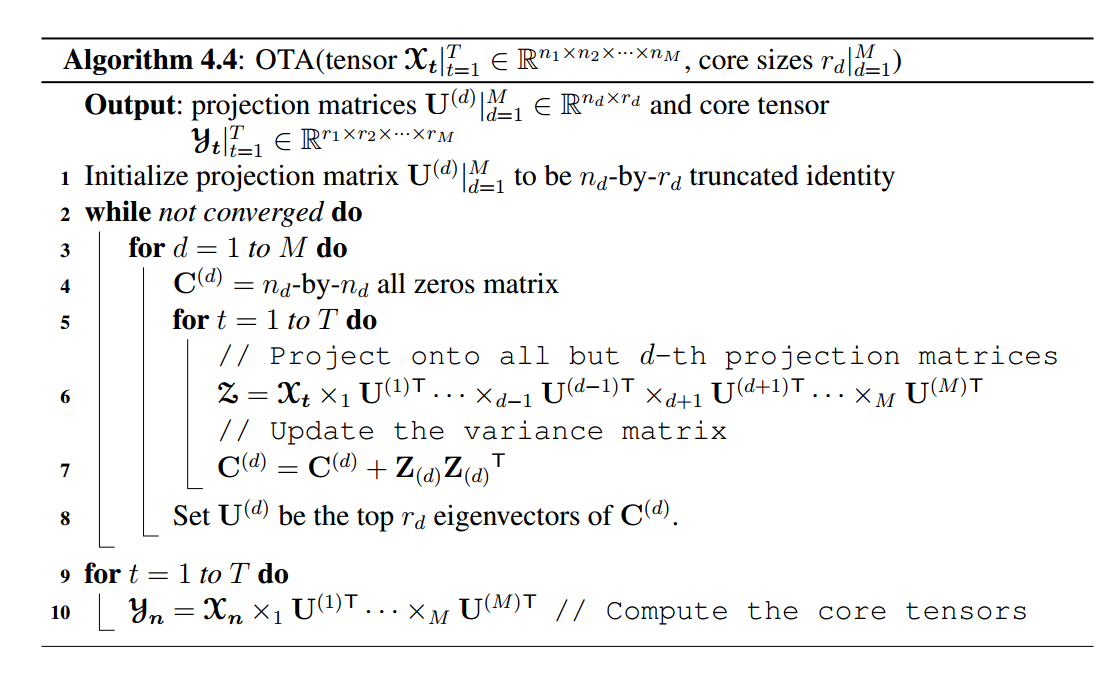

The OTA pseudo-code [2]:

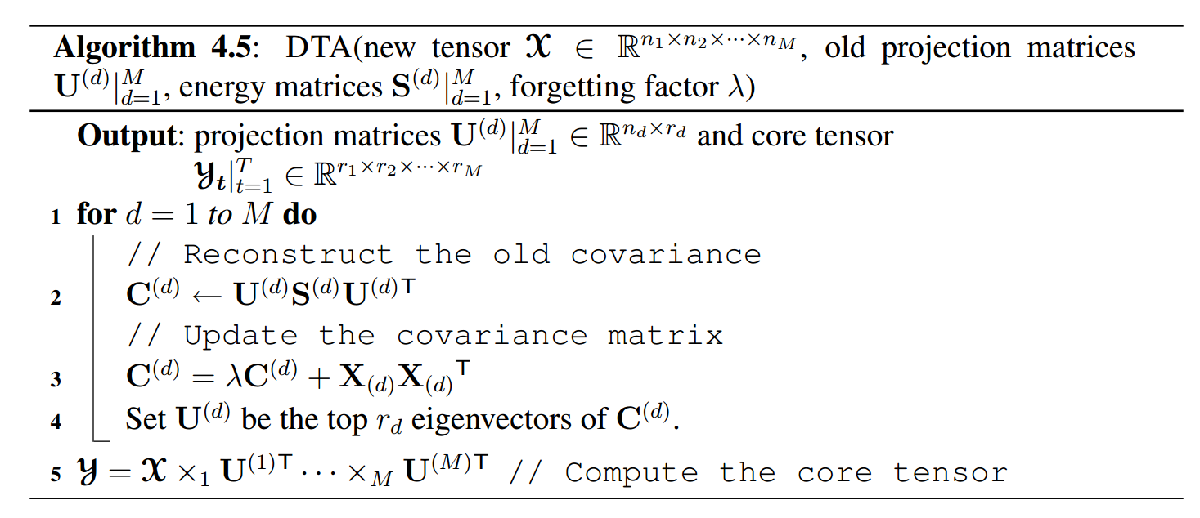

[1]: Sun, J., Tao, D. and Faloutsos, C., 2006, August. Beyond streams and graphs: dynamic tensor analysis. In *Proceedings of the 12th ACM SIGKDD international conference on Knowledge discovery and data mining* (pp. 374-383).

[2]: Sun, J., 2008. Incremental pattern discovery on streams, graphs and tensors. *ACM SIGKDD Explorations Newsletter*, *10*(2), pp.28-29.

[I1, I2, I3, N] = deal(5, 5, 5, 100);

all_tenX = randn([I1, I2, I3, N]);
% transforming all_tenX into a sequence of cells
aux = size(all_tenX);
aux = num2cell(aux(1:end-1));
all_tenX = squeeze(mat2cell(all_tenX, aux{:},ones(1,size(all_tenX,ndims(all_tenX)))));
% calling OTA - Offline Tensor Analysis
[all_U, all_tenY, Cd] = ota(all_tenX, [5,5,5]);
all_tenX_hat = cell(numel(all_tenX),1);
for i=1:numel(all_tenX_hat)
    all_tenX_hat{i} = nmodeproduct(all_tenY{i}, all_U, num2cell(1:numel(all_U)));
end

nmse = cellfun(@(x,y)norm(tensor(x-y))/norm(tensor(x)),all_tenX, all_tenX_hat);
nmse = sum(nmse)/numel(all_tenX)

nmse = 1.2705e-15

tenX_new = randn([I1, I2, I3]);
[tenY_new, all_U_new] = dta(tenX_new, Cd);
tenX_new_hat = nmodeproduct(tenY_new, all_U_new, num2cell(1:numel(all_U_new)));
nse = norm(tensor(tenX_new-tenX_new_hat))/norm(tensor(tenX_new))

nse = 1.0150e-15

function [all_U_new, all_tenY, Cd] = ota(all_tenX, tenY_size)
% initializing tenX_size, n, N, and loop parameters
error_min = 1e-3;
max_iter = 1e3;
n = length(all_tenX);
N = ndims(all_tenX{1});
tenX_size = size(all_tenX{1});
% initializing the projection matrices U in and out
all_U_current = cellfun(@eye, num2cell(tenX_size), 'UniformOutput', false);
all_U_current = cellfun(@(x,r)x(:,1:r), all_U_current, num2cell(tenY_size), 'UniformOutput', false);
all_U_new = cell(N,1);
Cd = cell(N,1);
% OTA - Offline Tensor Analysis
for iter = 1:max_iter
    for d=1:N
        all_U_but_d = all_U_current(setdiff(1:N,d));
        all_U_but_d_trans =  cellfun(@(x)x.', all_U_but_d, 'UniformOutput', false); % U^T
        Cd{d} = zeros([tenX_size(d) tenX_size(d)]);
        for i=1:n
            Z = nmodeproduct(all_tenX{i}, all_U_but_d_trans, num2cell(setdiff(1:N,d)));
            Z = nmodeunfold(Z, d);
            Cd{d} = Cd{d}+Z*Z.';
        end
        [V,~] = eig(Cd{d});
        all_U_new{d} = V(1:tenX_size(d), 1:tenY_size(d));
    end

    all_U_out_mult = cellfun(@(x)(x.'*x - eye(size(x.'*x))), all_U_new, 'UniformOutput', false);
    all_U_out_mult = cellfun(@(x)sum(diag(x)), all_U_out_mult, 'UniformOutput', false);
    all_check = [all_U_out_mult{:}]<=error_min;
    if all(all_check)
        break;
    else
        all_U_current = all_U_new;
    end
end

all_tenY = cell(n,1);
all_U_new_trans =  cellfun(@(x)x.', all_U_new, 'UniformOutput', false); % U^T
for i=1:n
    all_tenY{i} = nmodeproduct(all_tenX{i}, all_U_new_trans, num2cell(1:N));
end
end

function [tenY_new, all_U_new] = dta(tenX_new, Cd_old)
tenX_size = size(tenX_new);
N = ndims(tenX_new);
Cd_new = cell(numel(Cd_old),1);
all_U_new = cell(numel(Cd_old),1);
for d=1:N
    Xd = nmodeunfold(tenX_new, d);
    Cd_new{d} = Cd_old{d} + Xd*Xd.';
    [V,~] = eig(Cd_new{d});
    Rd = rank(Cd_new{d});
    all_U_new{d} = V(1:tenX_size(d), 1:Rd);
end
all_U_new_trans =  cellfun(@(x)x.', all_U_new, 'UniformOutput', false); % U^T
tenY_new = nmodeproduct(tenX_new, all_U_new_trans, num2cell(1:N));
end